**WILL TIRONE **

**MAT 275 **

**LAB 3 **

**Question 1**

**a) **

%ODE 
f = @(t,y) y; 

%exact soln 
t= linspace (0 ,1 ,100); y=2* exp(t); 

%approximations at N = n 
[t5 ,y5 ]= euler (f ,[0 ,1] ,2 ,5); 
[t50 ,y50 ]= euler (f ,[0 ,1] ,2 ,50); 
[t500 ,y500 ]= euler (f ,[0 ,1] ,2 ,500); 
[t5000 ,y5000 ]= euler (f ,[0 ,1] ,2 ,5000); 

N = [5 50 500 5000]';
Approximation = [y5(end) y50(end) y500(end) y5000(end)]';
Error = y(end) - Approximation;
Ratio = [0 Error(1)/Error(2) Error(2)/Error(3) Error(3)/Error(4)]';

%apparently I can't mix and match strings and numbers in tables, but the first ratio
%should be N/A
Data = table(N, Approximation, Error, Ratio)

Data = 4×4 table
     N      Approximation      Error       Ratio 
    ____    _____________    __________    ______

       5       4.9766           0.45992         0
      50       5.3832          0.053388    8.6148
     500       5.4311         0.0054266    9.8381
    5000        5.436        0.00054356    9.9835


**b) Examine the last column. How does the ratio of consecutive errors relate to the number of**

**steps used? Your answer to this question should confirm the fact that Euler's method is a**

**first-order method. That is, every time the step size is decreased by a factor of k, the error**

**is also reduced (approximately) by the same factor, k1 = k.**

**- **It appears that the consecutive errors are decreasing by a factor of 10 each time. From the instructions, it's noted that "every time the step size is decreased by a factor of k, the error is reduced approximately by the same factor k^1 = k...". As N is increasing, the step size is decreasing, thus we can see that when we move from, say, N=50 to N=500, the error is approximately 1/10th of the previous step. 

**c) Recall the geometrical interpretation of Euler's method based on the tangent line. Using this**

**geometrical interpretation, can you explain why the Euler approximations yN underestimate**

**the solution y? **

**- **(The plot below isn't part of the lab but it helps me understand the error).

- The red line below is the exact solution to the function; because the approximations are below this line, they are underestimates. If we drew a line from a point on either the green or blue line straight up to the exact solution, this would be the error (y - yN). In the table above, y50 is a much better approximation, with a lower error, than y5. This is confirmed by looking at the graph - as t grows larger , the blue line moves farther and farther away while the green is fairly close. If I graphed y500 or y5000, they would almost entirely replicate the actual solution. 

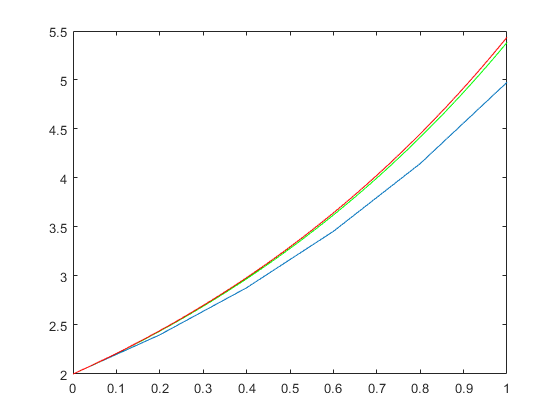

plot (t5 ,y5 ,t50,y50, 'g',t,y, 'r');

**Question 2 **

**For the IVP **

### 
$$y' = -4.5y, y(0) = 1$$


**with solution **

### 
$$y = e^{-4.5t}$$


**a)**

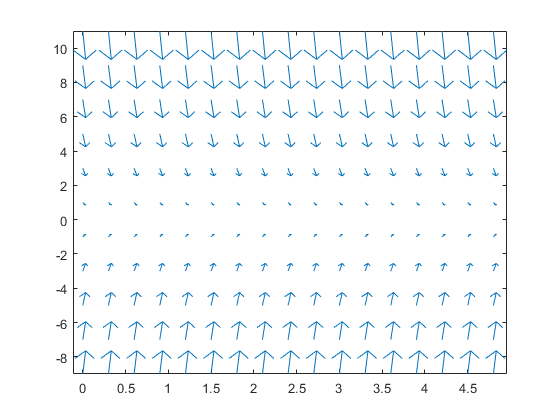

t = 0:0.3:5; y = -9:2:11; % define a grid in t & y directions
[T,Y] = meshgrid (t,y); % create 2d matrices of points in ty - plane
dT = ones ( size (T)); %dt =1 for all points
dY = -4.5*Y; %dy = -4.5*y; this is the ODE
quiver (T,Y,dT ,dY) % draw arrows (t,y)->(t+dt , t+dy)
axis tight % adjust look
hold on

**b) **

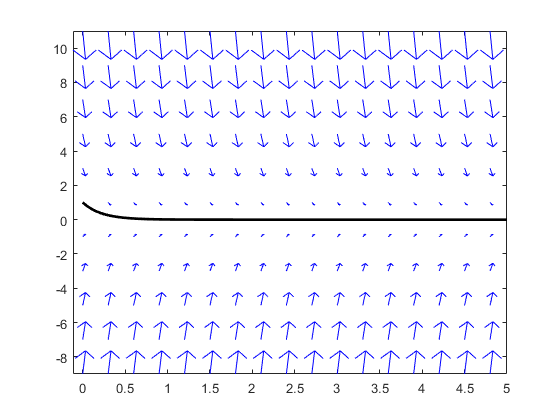

t1 = linspace(0,5,100); 
y1 = exp(-4.5 .* t1); 
t = 0:0.3:5; y = -9:2:11; % define a grid in t & y directions
[T,Y] = meshgrid (t,y); % create 2d matrices of points in ty - plane
dT = ones ( size (T)); %dt =1 for all points
dY = -4.5*Y; %dy = -4.5*y; this is the ODE
quiver (T,Y,dT ,dY,'b') % draw arrows (t,y)->(t+dt , t+dy)
axis tight % adjust look
hold on
plot(t1,y1, 'k', 'LineWidth', 2)

**c) Based on the slope fi eld and the geometrical meaning of Euler's method explain why the approximations are so inaccurate for this particular value of the stepsize.**

Based on Euler's method: $y_1 = y_0 + hf(t_0, y_0) $ with a relatively large step size, h, and small N, it seems obvious that $y_1 $ will not very closely approximate $y(t_0) $. Geometrically, because the approximation is above and below the line, increasingly as t increases, the approximation is getting less accurate as t grows large. 

I believe this has something to do with the solution having stable convergence at y = 0. Because the step size is so large, it is "overshooting" the actual solution. Then, when the slope is in the opposite direction, going from one side of 0 to the other from t=0.5 to t=1 for example, the error gets larger and larger while changing signs. 

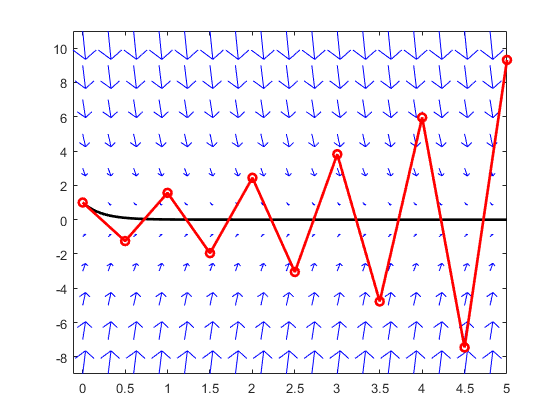

%ODE 
f=@(t,y) -4.5*y;

%approximations at N = n 
[t10 ,y10 ]= euler (f, [0,5] ,1 ,10); 

plot(t10,y10,'ro-','linewidth',2)

**d) **

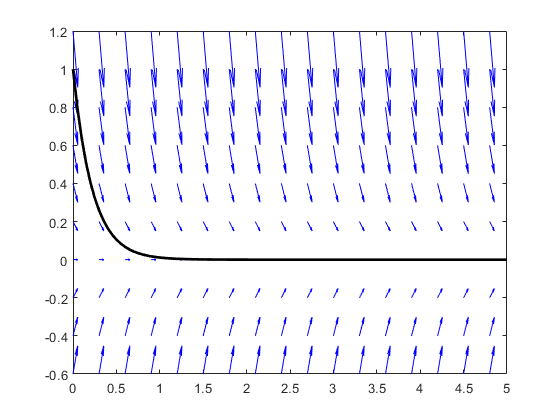

t1 = linspace(0,5,100); 
y1 = exp(-4.5 .* t1); 
t = 0:0.3:5; y = -0.6:.2:1.3; % define a grid in t & y directions
[T,Y] = meshgrid (t,y); % create 2d matrices of points in ty - plane
dT = ones ( size (T)); %dt =1 for all points
dY = -4.5*Y; %dy = -4.5*y; this is the ODE
quiver (T,Y,dT ,dY,'b') % draw arrows (t,y)->(t+dt , t+dy)
axis tight % adjust look
hold on
plot(t1,y1, 'k', 'LineWidth', 2) 

**d) continued **

**- **While similar to the previous example, this solution has a large enough N that the approximation is able to "correct" and not overshoot the actual solution significantly. 

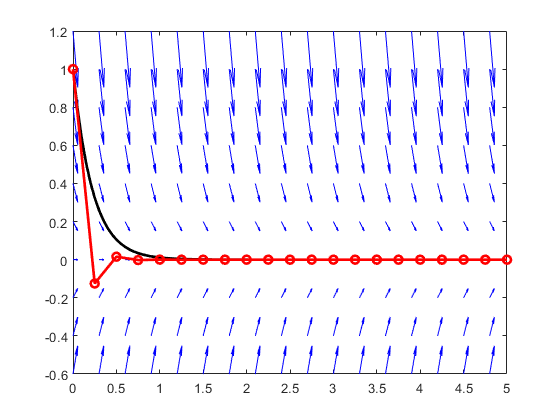

%ODE 
f=@(t,y) -4.5*y;

%approximations at N = n 
[t10 ,y10 ]= euler (f, [0,5] ,1 ,20); 

plot(t10,y10,'ro-','linewidth',2)

**Question 3**

type impeuler.m

 function [t,y] = impeuler(f,tspan,y0,N)

% Solves the IVP y' = f(t,y), y(t0) = y0 in the time interval tspan = [t0,tf]
% using Euler's method with N time steps.
%  Input:
%  f = name of inline function or function M-file that evaluates the ODE
%          (if not an inline function,  use: euler(@f,tspan,y0,N))
%          For a system, the f must be given as column vector.
%  tspan = [t0, tf] where t0 = initial time value and tf = final time value
%  y0  = initial value of the dependent variable. If solving a system,
%           initial conditions must be given as a vector.
%  N   = number of steps used.
% Output:
%  t = vector of time values where the solution was computed
%  y = vector of computed solution values.

m = length(y0);
t0 = tspan(1);
tf = tspan(2);
h = (tf-t0)/N;             % evaluate the time step size
t = linspace(t0,tf,N+1);    % create the vector of t values
y = zeros(m,N+1);   % allocate memory for the output y
y(:,1) = y0';              % set initial condition
for n

f = @(t,y) y; 
[t5,y5] = impeuler(f,[0,1],2,5)

t5 =          0
    0.2000
    0.4000
    0.6000
    0.8000
    1.0000


y5 =     2.0000
    2.4400
    2.9768
    3.6317
    4.4307
    5.4054


**Question 4 **

**Examine the last column. How does the ratio of the errors relate to the number of steps used? **

**a and b) **

**   -  **As mentioned in the lab instructions, the improved Euler method is a "second-order" method because as N is increased by a factor of k, the error is approximately reduced by that amount. Below, the error decreases from 0.0311 to 0.000357 when N increased by k*5 where k = 10. I think this could also be interpreted as N increases by a factor of 10, the error decreases by a factor of 100. Additionally, the ratio of errors is about 100 as N grows large, meaning the error is 100 times smaller than the previous step. 

f = @(t,y) y; 
t= linspace (0,1,100); y=2* exp(t); 

%approximations at N = n 
[t5 ,y5 ]= impeuler (f ,[0 ,1] ,2 ,5); 
[t50 ,y50 ]= impeuler (f ,[0 ,1] ,2 ,50); 
[t500 ,y500 ]= impeuler (f ,[0 ,1] ,2 ,500); 
[t5000 ,y5000 ]= impeuler (f ,[0 ,1] ,2 ,5000); 

N = [5 50 500 5000]';
Approximation = [y5(end) y50(end) y500(end) y5000(end)]';
Error = y(end) - Approximation;
Ratio = [0 Error(1)/Error(2) Error(2)/Error(3) Error(3)/Error(4)]';

%apparently I can't mix and match strings and numbers in tables, but the first ratio
%should be N/A
Improved_Data = table(N, Approximation, Error, Ratio)

Improved_Data = 4×4 table
     N      Approximation      Error       Ratio 
    ____    _____________    __________    ______

       5       5.4054          0.031147         0
      50       5.4362        0.00035703    87.239
     500       5.4366        3.6189e-06    98.657
    5000       5.4366        3.6238e-08    99.865


**Question 5) **

- a) and b) below are identical to question 2; part c) and d) are where impeuler is used. 

**Results Comparison**

- With a small step size, it looks like the improved Euler method is just as innacurate as the standard method. I doubt either of these results would be very useful in approximating a function. Of note, though, the improved euler method only overstates the function's actual solution (increasingly as t increases) while the standard method went from overstating to understating. 

I noticed the same result with the larger step size (N=20); where the standard method underapproximated the actual solution initially, the improved method overapproximated. Because the improved method is the result of "averaging" two slopes, the approximation is fairly smooth even at a realtively small N. Clearly the improved method is more accurate, although it seems that both models need at least N > 10 to be useful. 

**For the IVP **

### 
$$y' = -4.5y, y(0) = 1$$


**with solution **

### 
$$y = e^{-4.5t}$$


**a)**

clear

t = 0:0.3:5; y = -9:2:11; % define a grid in t & y directions
[T,Y] = meshgrid (t,y); % create 2d matrices of points in ty - plane
dT = ones ( size (T)); %dt =1 for all points
dY = -4.5*Y; %dy = -4.5*y; this is the ODE
quiver (T,Y,dT ,dY) % draw arrows (t,y)->(t+dt , t+dy)
axis tight % adjust look
hold on

**b) **

t1 = linspace(0,5,100); 
y1 = exp(-4.5 .* t1); 
t = 0:0.3:5; y = -9:2:11; % define a grid in t & y directions
[T,Y] = meshgrid (t,y); % create 2d matrices of points in ty - plane
dT = ones ( size (T)); %dt =1 for all points
dY = -4.5*Y; %dy = -4.5*y; this is the ODE
quiver (T,Y,dT ,dY,'b') % draw arrows (t,y)->(t+dt , t+dy)
axis tight % adjust look
hold on
plot(t1,y1, 'k', 'LineWidth', 2)

**c) **

- similar to Question 2, because of the large step size, the approximation is getting less and less accurate as t increases. Rather than jumping above and below the solution, though, this curve rises smoothly. However, it is still very innacurate. 

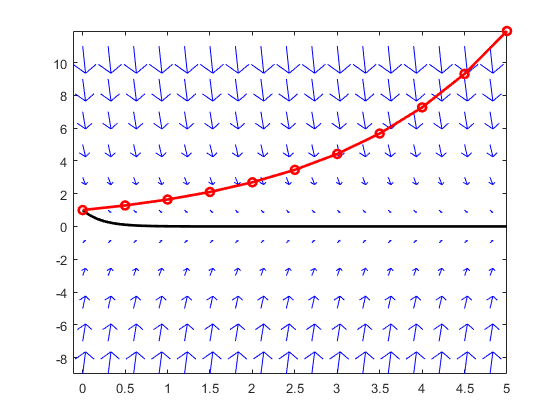

%ODE 
f=@(t,y) -4.5*y;

%approximations at N = n 
[t10_imp ,y10_imp ]= impeuler(f, [0,5] ,1 ,10); 

plot(t10_imp,y10_imp,'ro-','linewidth',2)

**d) **

clear

t1 = linspace(0,5,100); 
y1 = exp(-4.5 .* t1); 
t = 0:0.3:5; y = -0.6:.2:1.3; % define a grid in t & y directions
[T,Y] = meshgrid (t,y); % create 2d matrices of points in ty - plane
dT = ones ( size (T)); %dt =1 for all points
dY = -4.5*Y; %dy = -4.5*y; this is the ODE
quiver (T,Y,dT ,dY,'b') % draw arrows (t,y)->(t+dt , t+dy)
axis tight % adjust look
hold on
plot(t1,y1, 'k', 'LineWidth', 2) 

**d) continued **

- As expected, the smaller step size results in a more accurate approximation. The below graph also shows how the improved Euler method is the average of two slopes because it does not dip below the actual solution in contrast to the standard Euler method plots. 

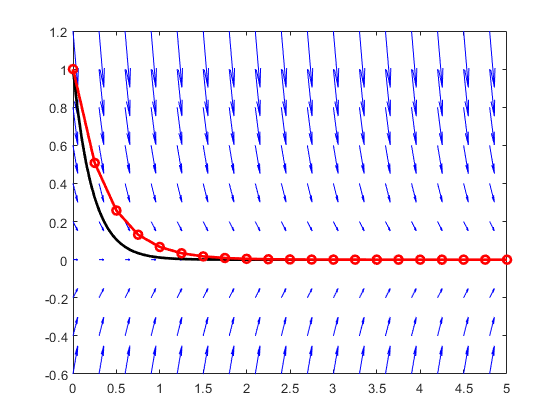

%ODE 
f=@(t,y) -4.5*y;

%approximations at N = n 
[impt10 ,impy10 ]= impeuler(f, [0,5] ,1 ,20); 

plot(impt10,impy10,'ro-','linewidth',2)